


% 读取数据文件
filename = './2025.10.1 test/incremental_regression_test_5.log';
fid = fopen(filename, 'r');

% 跳过注释行
fgetl(fid);

% 读取cycle数量
cycle = str2double(fgetl(fid));

% 读取各数据行
total_length = str2num(fgetl(fid));
ave_sync_length = str2num(fgetl(fid));
sync_net_number = str2num(fgetl(fid));
failed_net = str2num(fgetl(fid));
reg_monopoliezd = str2num(fgetl(fid));
reg_mixed = str2num(fgetl(fid));

fclose(fid);

% 创建时间轴
time = 1:cycle;

% 创建大画布
figure('Position', [100, 100, 1200, 1200]);

% 第一张图：failed_net（原第一张图的剩余部分）
subplot(3, 1, 1);
hold on;

% 绘制failed_net原始数据
plot(time, failed_net, 'g-', 'LineWidth', 1.5, 'DisplayName', 'failed\_net');
plot(time, ave_sync_length, 'r-', 'LineWidth', 1.5, 'DisplayName', 'ave\_sync\_length');

% 计算并绘制平均值
avg_failed_net = mean(failed_net);
avg_ave_sync_length = mean(ave_sync_length);
yline(avg_failed_net, 'g--', 'LineWidth', 1, 'DisplayName', sprintf('avg failed\\_net = %.2f', avg_failed_net));
yline(avg_ave_sync_length, 'r--', 'LineWidth', 1, 'DisplayName', sprintf('avg ave\\_sync\\_length = %.2f', avg_ave_sync_length));

xlabel('Cycle');
ylabel('Values');
title('Analysis of failed\_net and ave\_sync\_length');
legend('Location', 'east');
grid on;
hold off;

% 第二张图：reg_monopoliezd, reg_mixed（保持不变）
subplot(3, 1, 2);
hold on;

% 绘制原始数据
plot(time, reg_monopoliezd, 'm-', 'LineWidth', 1.5, 'DisplayName', 'reg\_monopoliezd');
plot(time, reg_mixed, 'c-', 'LineWidth', 1.5, 'DisplayName', 'reg\_mixed');

% 计算并绘制平均值
avg_reg_monopoliezd = mean(reg_monopoliezd);
avg_reg_mixed = mean(reg_mixed);

yline(avg_reg_monopoliezd, 'm--', 'LineWidth', 1, 'DisplayName', sprintf('avg reg\\_monopoliezd = %.4f', avg_reg_monopoliezd));
yline(avg_reg_mixed, 'c--', 'LineWidth', 1, 'DisplayName', sprintf('avg reg\\_mixed = %.4f', avg_reg_mixed));

xlabel('Cycle');
ylabel('Values');
title('Analysis of reg\_monopoliezd and reg\_mixed');
legend('Location', 'east');
grid on;
hold off;

% 第三张图：total_length, ave_sync_length（新增子图）
subplot(3, 1, 3);
hold on;

% 绘制原始数据
plot(time, total_length, 'b-', 'LineWidth', 1.5, 'DisplayName', 'total\_length');


% 计算并绘制平均值
avg_total_length = mean(total_length);
yline(avg_total_length, 'b--', 'LineWidth', 1, 'DisplayName', sprintf('avg total\\_length = %.2f', avg_total_length));


xlabel('Cycle');
ylabel('Values');
title('Analysis of total\_length');
legend('Location', 'best');
grid on;
hold off;

% 显示统计信息
fprintf('=== 数据统计信息 ===\n');

=== 数据统计信息 ===


fprintf('总周期数: %d\n', cycle);

总周期数: 30


fprintf('\n数据统计:\n');


数据统计:


fprintf('total_length - 平均值: %.4f, 标准差: %.4f, 范围: [%d, %d]\n', ...
    mean(total_length), std(total_length), min(total_length), max(total_length));

total_length - 平均值: 685.2333, 标准差: 4.8258, 范围: [684, 708]


fprintf('ave_sync_length - 平均值: %.4f, 标准差: %.4f, 范围: [%.4f, %.4f]\n', ...
    mean(ave_sync_length), std(ave_sync_length), min(ave_sync_length), max(ave_sync_length));

ave_sync_length - 平均值: 8.5421, 标准差: 0.0636, 范围: [8.5263, 8.8421]


fprintf('failed_net - 平均值: %.4f, 标准差: %.4f, 范围: [%d, %d]\n', ...
    mean(failed_net), std(failed_net), min(failed_net), max(failed_net));

failed_net - 平均值: 4.0000, 标准差: 0.0000, 范围: [4, 4]



fprintf('\n第二组数据统计:\n');


第二组数据统计:


fprintf('reg_monopoliezd - 平均值: %.6f, 标准差: %.6f, 范围: [%.6f, %.6f]\n', ...
    mean(reg_monopoliezd), std(reg_monopoliezd), min(reg_monopoliezd), max(reg_monopoliezd));

reg_monopoliezd - 平均值: 0.849220, 标准差: 0.015626, 范围: [0.816742, 0.887387]


fprintf('reg_mixed - 平均值: %.6f, 标准差: %.6f, 范围: [%.6f, %.6f]\n', ...
    mean(reg_mixed), std(reg_mixed), min(reg_mixed), max(reg_mixed));

reg_mixed - 平均值: 0.150780, 标准差: 0.015626, 范围: [0.112613, 0.183258]


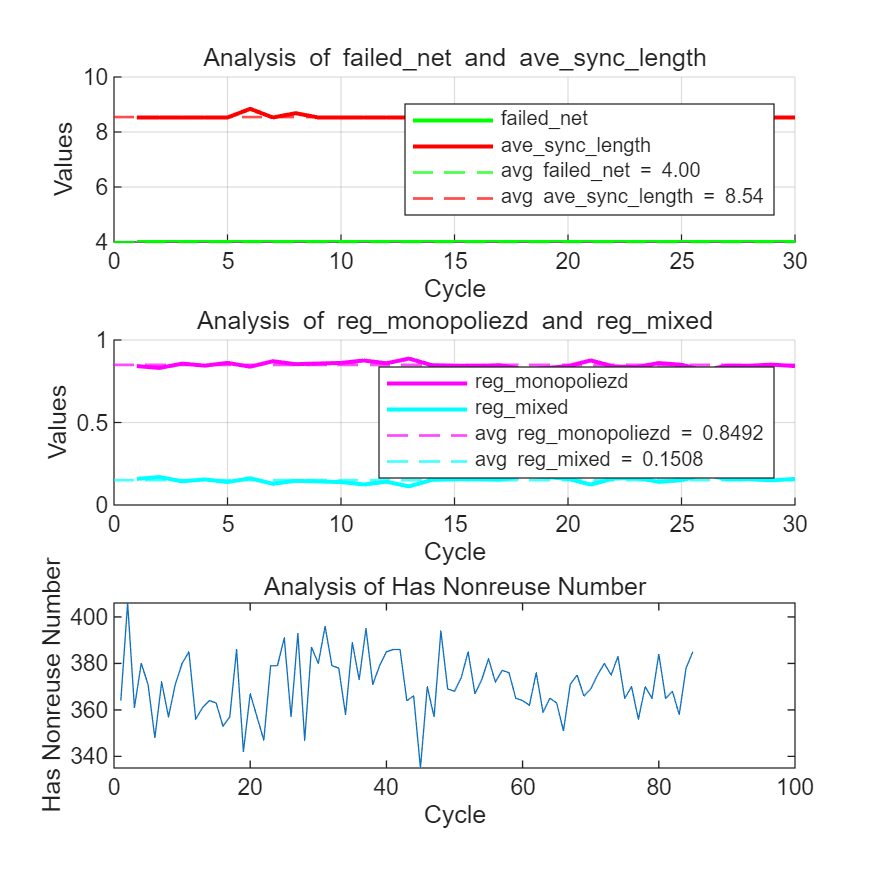

y1 = [364, 406, 361, 403, 380, 371, 348, 372, 357, 371, 380, 385, 356, 361, 364, 363, 353, 357, 386, 342, 367, 357, 347, 432, 379, 379, 391, 357, 393, 347, 387, 380, 396, 379, 378, 358, 389, 373, 395, 371, 379, 385, 386, 386, 364, 366, 335, 370, 357, 394, 369, 368, 374, 385, 409, 367, 373, 382, 372, 377, 414, 419, 376, 365, 364, 362, 414, 376, 411, 418, 359, 365, 407, 363, 351, 371, 375, 425, 366, 369, 375, 380, 275, 383, 365, 370, 356, 370, 365, 384, 365, 368, 358, 417, 378, 422, 421, 385, ];
y2 = [364, 406, 361, 380, 371, 348, 372, 357, 371, 380, 385, 356, 361, 364, 363, 353, 357, 386, 342, 367, 357, 347, 379, 379, 391, 357, 393, 347, 387, 380, 396, 379, 378, 358, 389, 373, 395, 371, 379, 385, 386, 386, 364, 366, 335, 370, 357, 394, 369, 368, 374, 385, 367, 373, 382, 372, 377, 376, 365, 364, 362, 376, 359, 365, 363, 351, 371, 375, 366, 369, 375, 380, 375, 383, 365, 370, 356, 370, 365, 384, 365, 368, 358, 378, 385];
x = 1:1:length(y2);
plot(x, y2)
title("Analysis of Has Nonreuse Number")
xlabel("Cycle")
ylabel("Has Nonreuse Number")